% Add an update, commit and push
cd('/Users/peterfish/Documents/Matlab-lib');
commitStr = sprintf('Matlab library update on %s', datestr(now));
evalc(['!git add -A; git commit -am "' commitStr '"; git push;']);

% struct g after sorting
% spikes from i-th file (experiment) and align the timestamps of 'all' cells relative to events.
% PD should provide timings of the events.
cd('/Users/peterfish/Documents/1__Retina_Study/DATA_2016/16-10-31');
%
[pd, ev_id, srate] = getpd('1031drift.h5');
save('pd.mat', 'pd');
load('16-10-31.mat');

if ~exist('g')
    load('16-11-07.mat');
end
if ~exist('pd')
    load('pd.mat');
end
% load ex struct
params = ex.stim{1}.params;
% Duration of repeat (one experiment)
ifi = ex.disp.ifi;
numframes = params.jumpevery;
n_session = params.n_session;
s_duration = numframes * ifi

s_duration = 1.4119

repeat_duration = n_session * s_duration

repeat_duration = 16.9425

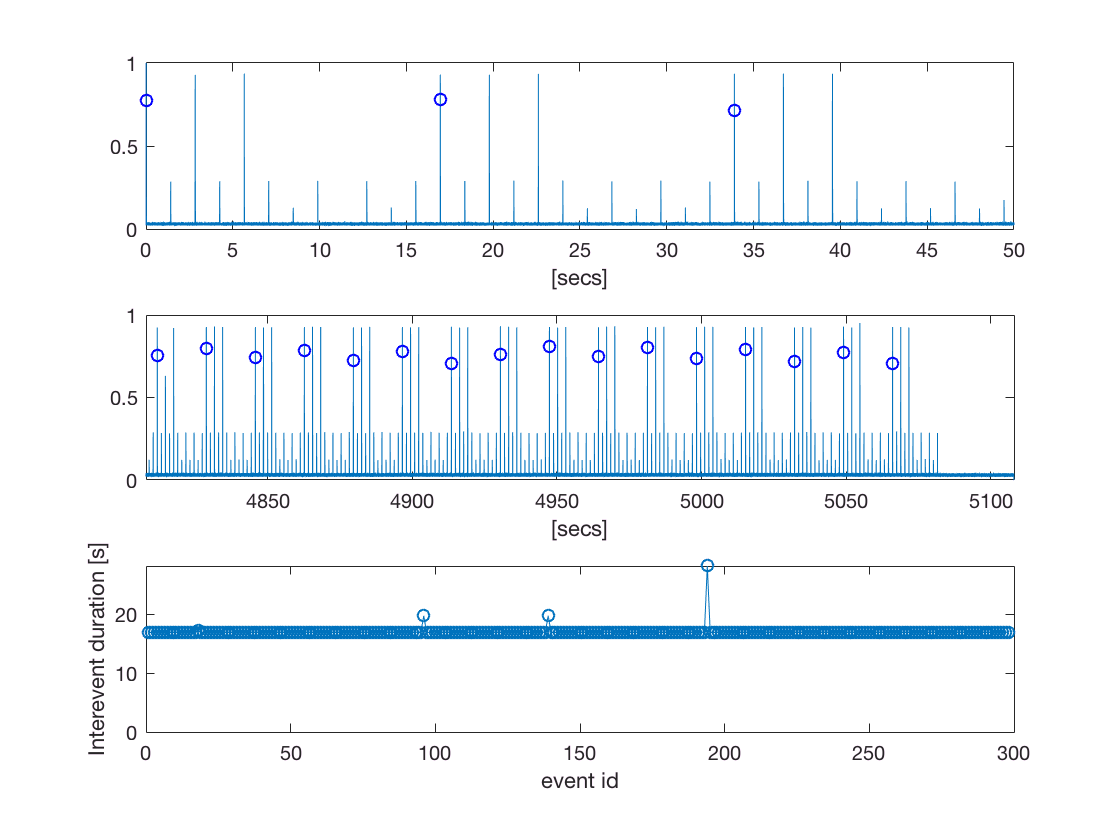

ans =              files: {'1107obj.h5'  '1107rf.h5'}
    N_sorted_cells: 13
               CHs: [14 18 20 23 24 25 28 30 32 41 47 48]
             times: {[1x13206 double]  [1x797 double]}
                ch: 14


% event timeedges
min_interval_secs = 0.9*repeat_duration;
ev_secs = pd_event_display(pd, min_interval_secs, 0.7);

## Spike timestamps of j-th cell and Align relative to trigger signals (PD)

s = list_sorted_cells(g);

i_file = 1; % file id (experiment id)
j_cell = 7; % cell id
s(j_cell)

ans =              files: {'1107obj.h5'  '1107rf.h5'}
    N_sorted_cells: 13
               CHs: [14 18 20 23 24 25 28 30 32 41 47 48]
             times: {[1x9620 double]  [1x1357 double]}
                ch: 28


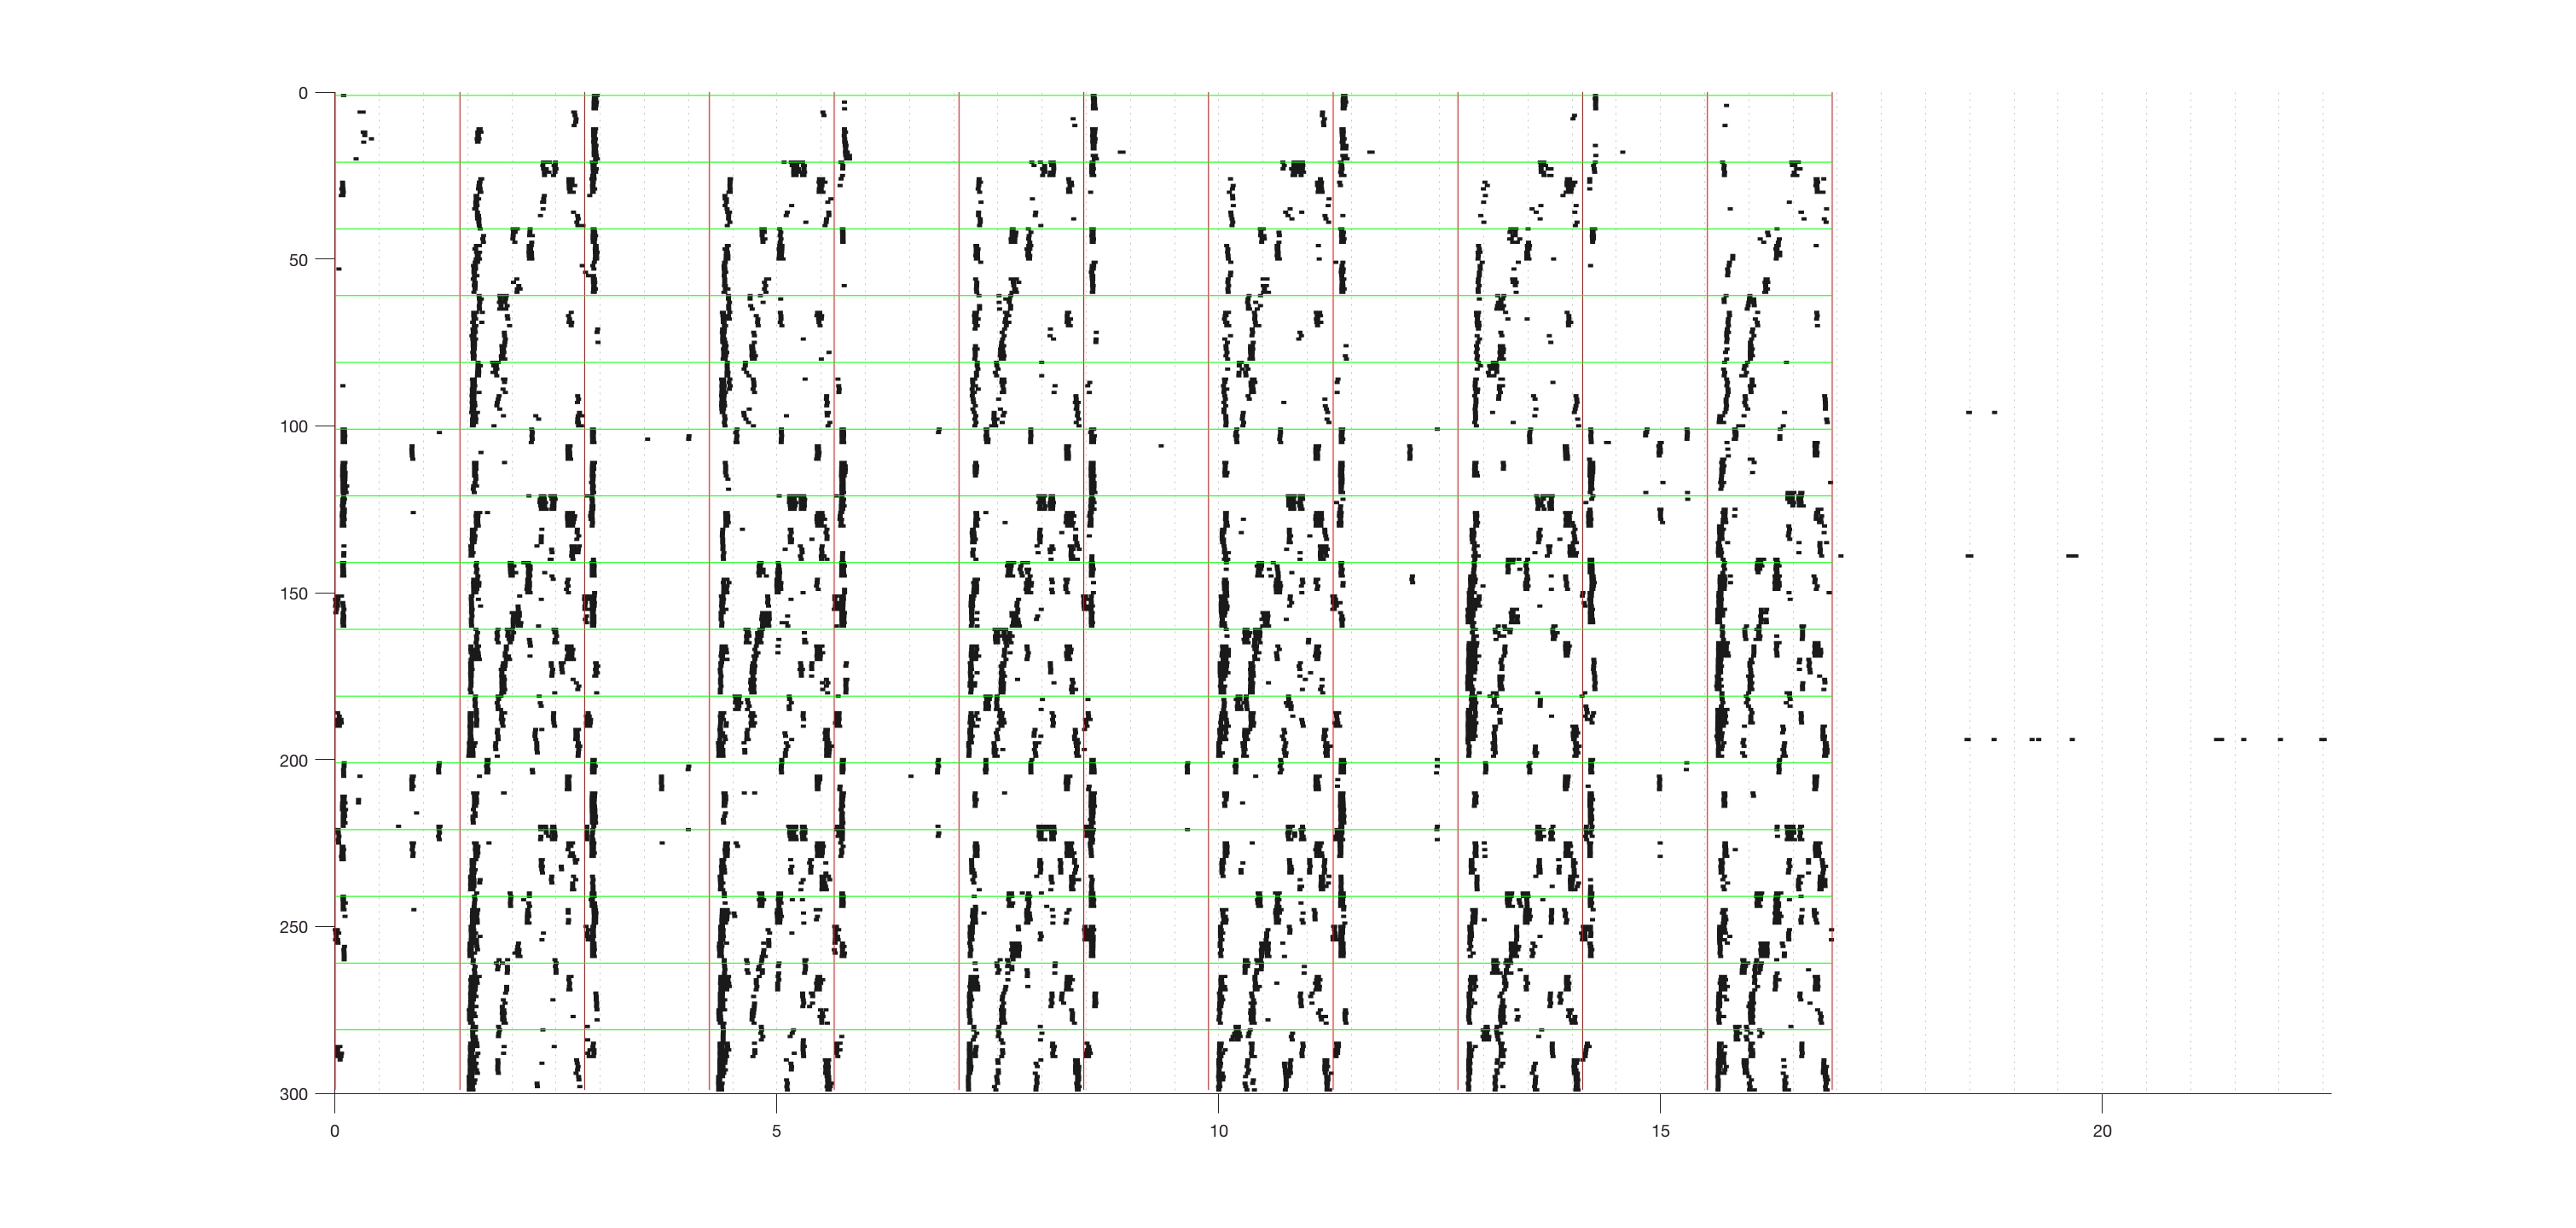


% Align spikes relative to PD trigger events 
spikes = align_sorted_cells(s, ev_secs, i_file);

% display
figure; 
H_line_every = params.n_jitter*params.n_repeat;
V_lines = (0:n_session) * s_duration;
myraster(spikes{j_cell}, H_line_every, V_lines); 
xlim([0, repeat_duration+4*s_duration]);

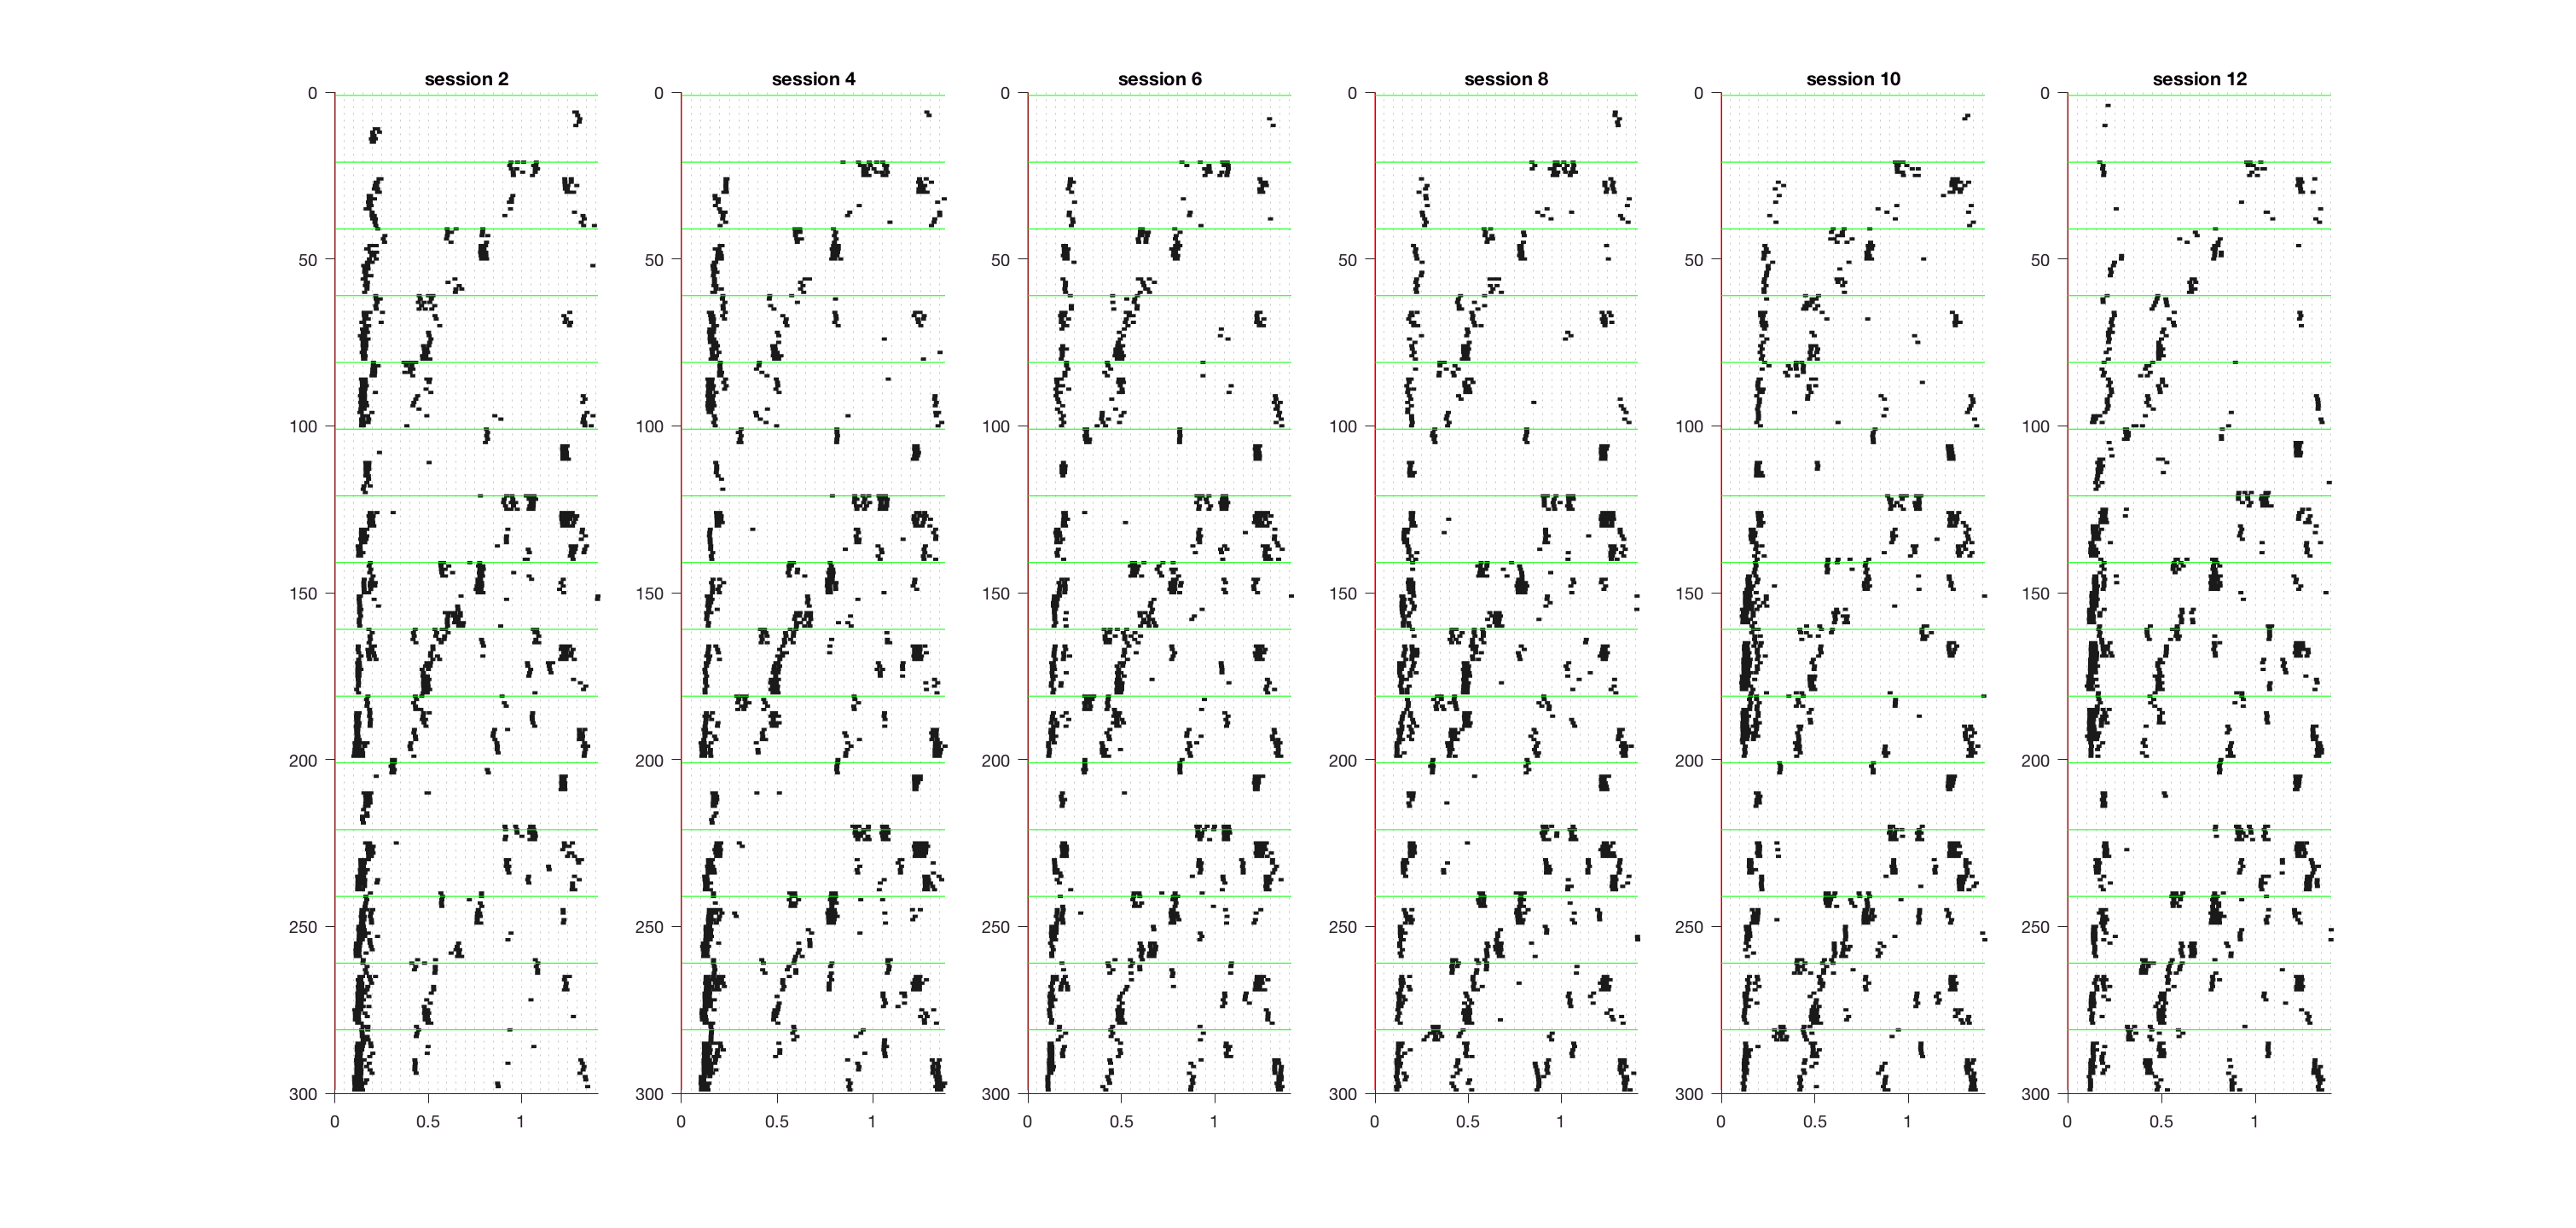

% Align (split) spikes relative to sessions
ev_session = 0:s_duration:s_duration*(n_session-1);
spikes_alined_session = split_to_event(spikes{j_cell}, ev_session);

% Focus on transitions
transitions = [2, 4, 6, 8, 10, 12];
n_transitions = length(transitions);
rate = cell(1, n_transitions);
figure;
for i = 1:n_transitions
    subplot(1, n_transitions, i);
    s_spikes = spikes_alined_session{transitions(i)};
    myraster(s_spikes, H_line_every, [0, s_duration]); title(['session ',num2str(transitions(i))]);
    %
    bin_size = 0.01;
    smoothing = 3;
    rate{i} = ts_rate_cell(s_spikes, [0 s_duration], bin_size, smoothing); % rate is an array
end

## Plot firing rate

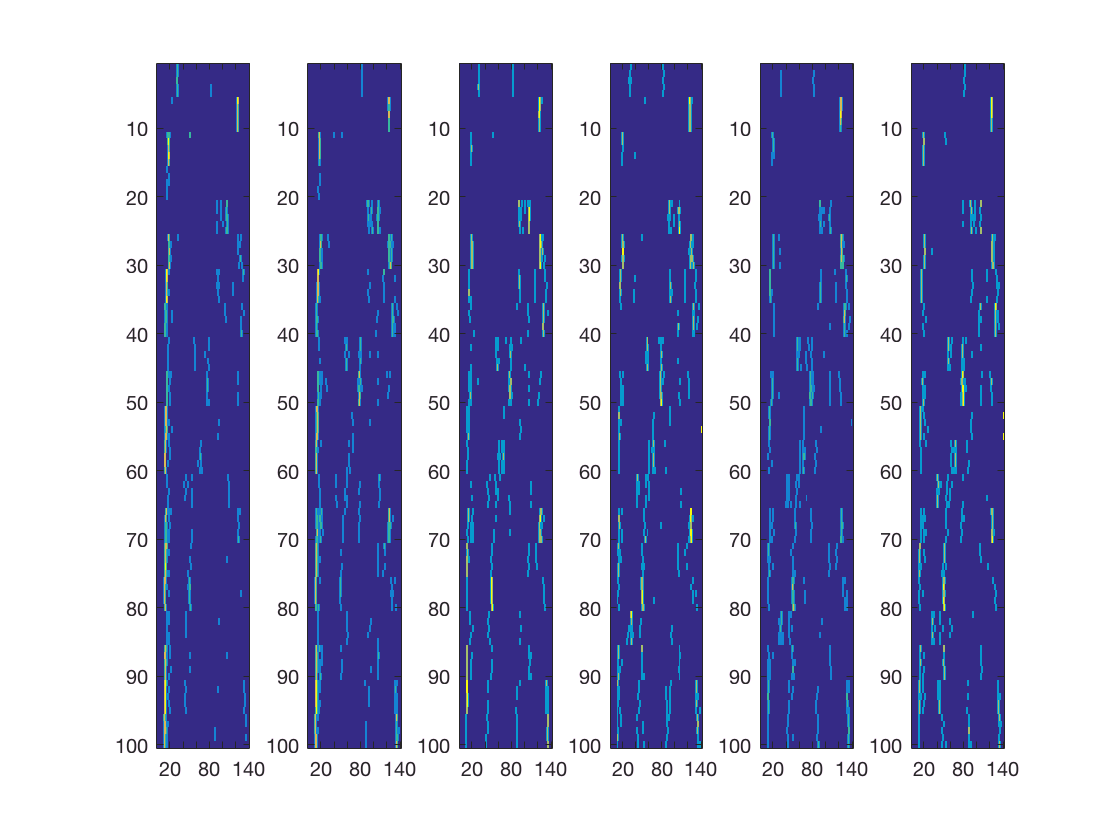

% line (experiment) range
i_exp = 201; % line id for experiment
n_exp = 100;    % # of lines
trigger_missing = 1;
i_exp = i_exp - trigger_missing;
%
figure; 
for i = 1:n_transitions
    subplot(1, n_transitions, i);
    imagesc(rate{i}(i_exp:i_exp+n_exp-1,:));
end

## Close up 'k-th' session for choosing appropriate time window 

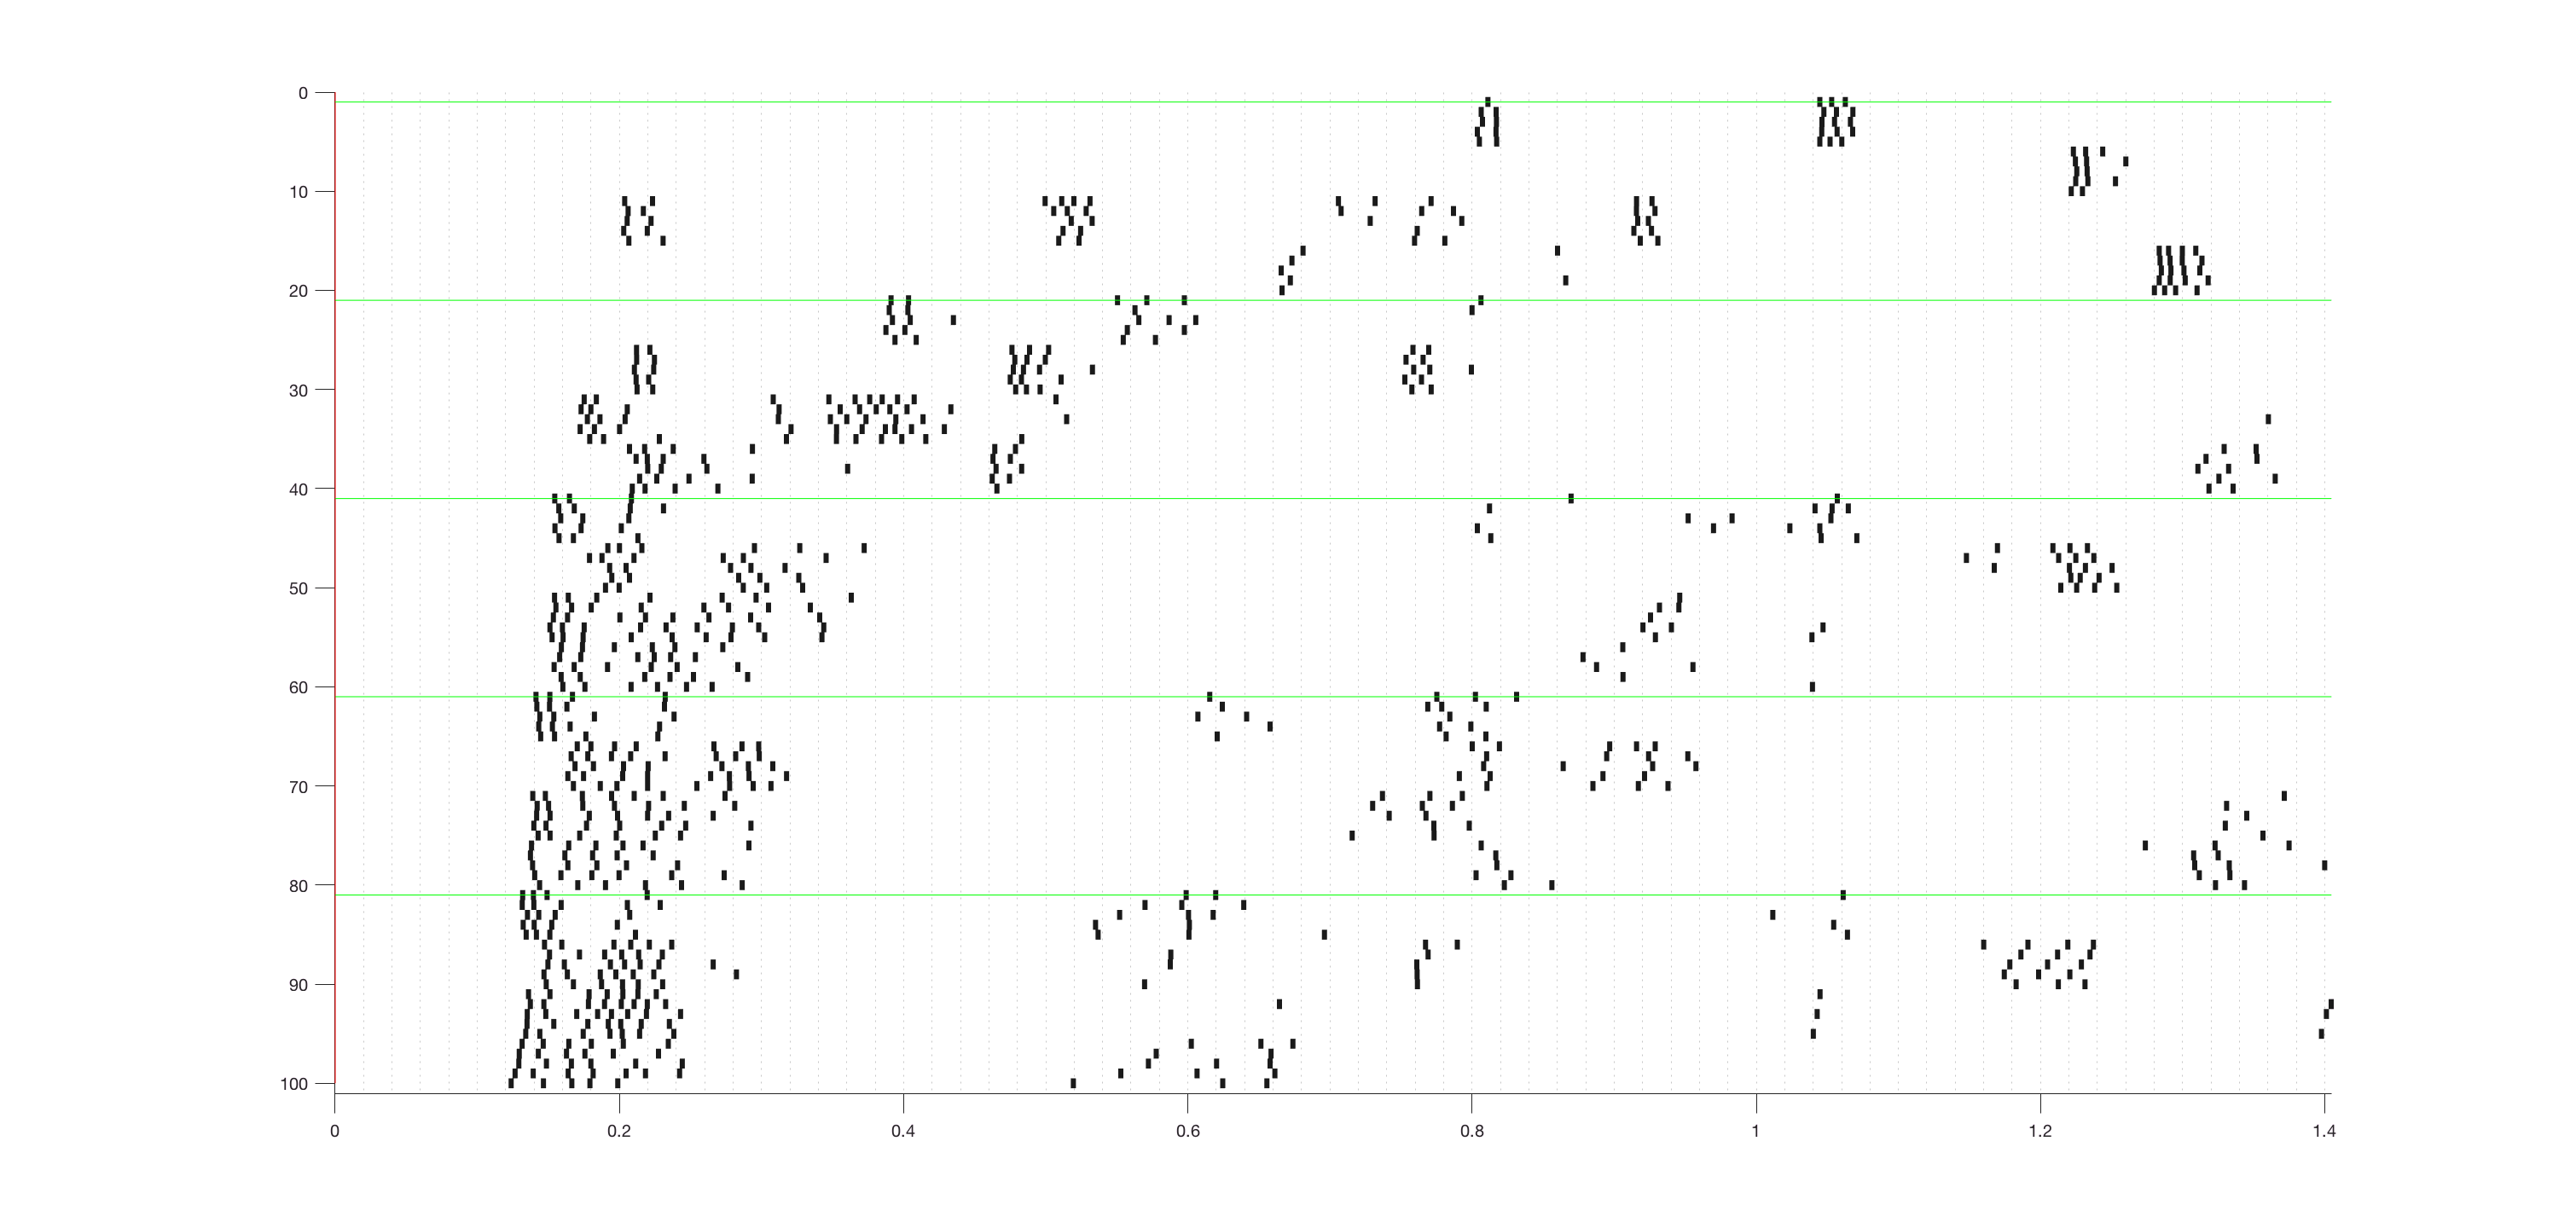

k_session = n_session;
s_spikes = spikes_alined_session{k_session}(i_exp:i_exp+n_exp-1);
figure; myraster(s_spikes, H_line_every);

## Analysis with 'Firing Rate':

Avg & STD over identical repeats

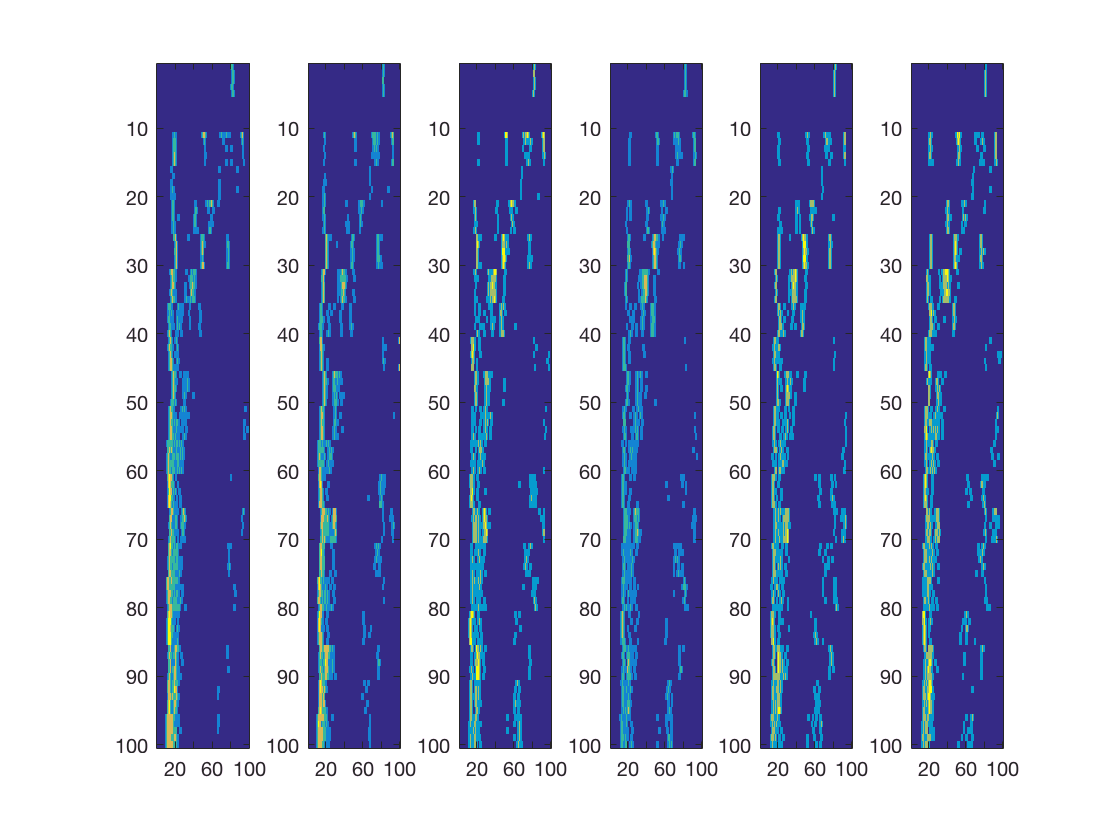

t_window = [0, 1.0];
%t_window = [0 duration];
t_duration = t_window(2)-t_window(1);
% timestamps to firing rate (basically, binning & smoothing)
bin_size = 0.01;
smoothing = 3;
%
figure; title(['time window']);
for i = 1:n_transitions
    subplot(1, n_transitions, i);
    s_spikes = spikes_alined_session{transitions(i)}(i_exp:i_exp+n_exp-1,:);
    rate{i} = ts_rate_cell(s_spikes, t_window, bin_size, smoothing); % rate is an array
    imagesc(rate{i});
    ax = gca;
    ax.DataAspectRatioMode = 'auto';
    ax.PlotBoxAspectRatioMode = 'auto';
    ax.CameraViewAngleMode = 'auto';
end

S = sprintf('drift %d*', 1:n_transition); C = regexp(S, '*', 'split');

Undefined function or variable 'n_transition'.


D = regexp(S, '*', 'split');
legend(D{1:(end-1)});

[rate_avg, rate_std] = stat_every_all(    rate, n_repeat);
[rate_avg, rate_std] = stat_every_all(rate_avg, n_jitter);

[mean_r, peak_r, peak_t, first_t] = rate_analysis_all(rate_avg, bin_size);

## Tuning curves with different exp conditions (e.g. speed)

figure; hold on;
cellfun(@plot, peak_r);  
ylabel('Hz');